s0_add_paths;

## The loss landscape of NOA

% parameters
target = 'target'; ds = 2; roi = 1; n = 20;
wLst = linspace( -5,  5, n);
nLst = linspace(-10, 10, n);
model = normVarModel();
mse_land = nan(n, n);

% input 
E = dataloader(stdnormRootPath, 'E_ori', target, ds, roi);
% output 
BOLD_tar = dataloader(stdnormRootPath, 'BOLD_target', target, ds, roi); 
for i = 1:n
    for j = 1:n
        param = [wLst(i), .0893, nLst(j)];
        BOLD_hat = model.forward(model, E, param);
        mse = double(mean((BOLD_tar - BOLD_hat).^2));
        mse_land(i, j) = mse;
    end
end

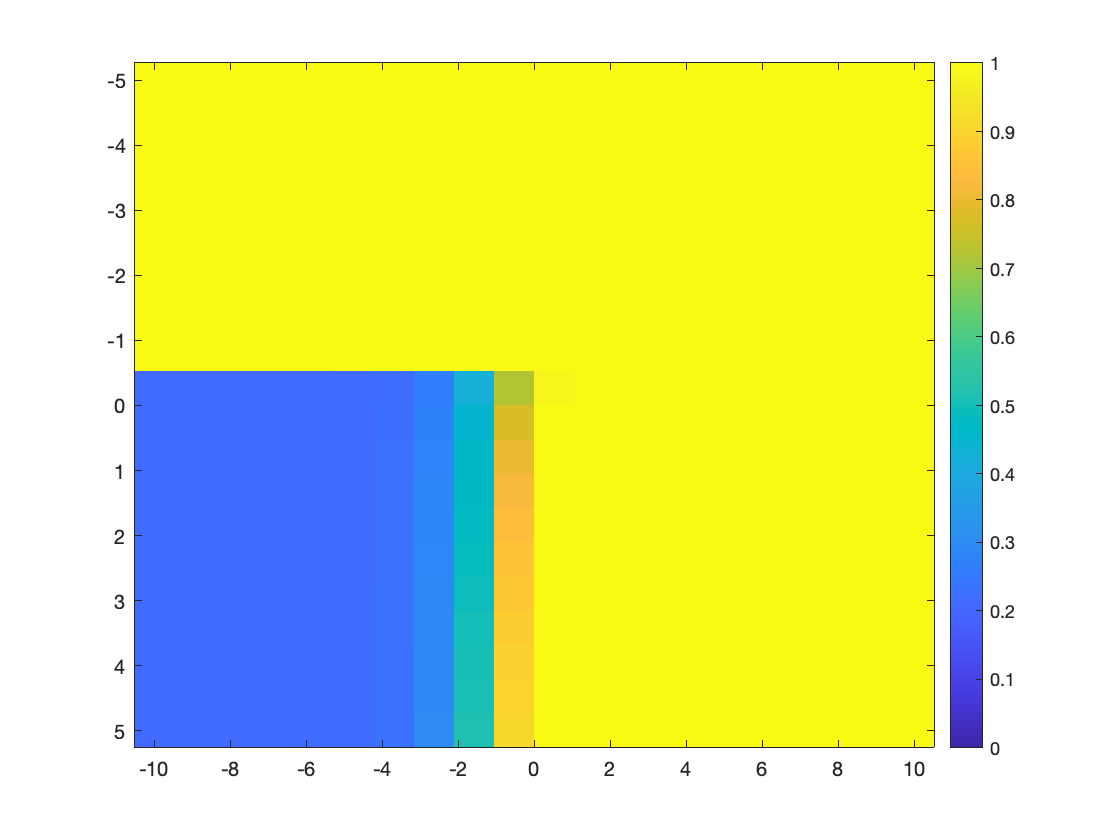

% visualize 
mse_land(imag(mse_land) ~= 0) = inf;
figure();
imagesc(nLst, wLst, mse_land,[0, 1]);
colorbar;

min(mse_land(:))

ans = 0.2136